clear
clc

## Template

This scripts is a template for how this program can be used. 1. Define the target payload and altitude. 2. Then contruct the two stages according to: stage_n = Stage(m_0, m_p, V_eff, A, C_d) 3. Set height and amount for programmed turn of first stage (meters, radians) 4. Construct an array of the used burnrates: burn_rates = [first_stage_pre_turn, first_after_turn, max_of_second_stage] 5. Set the plot_name variable to a distinct name identifiable to your rocket. 6. Run program, read print-out, observe results. Tweak rocket.

NOTES: - If program runs for long time the rocket has too low thrust and can't gain altitue. - The second stage uses an impulse delta V to get to the right orbit, here you might read negative values for the remaining fuel. This means that you do not have enough fuel for last delta V to get the right speed, even though you reach the right altitude.

clear all
close all

## Mission parameters

m_payload = 1000; % Our payload
target_altitude = 600000;

## Scaled Vega (first two stages)

This rocket is a scaled version of the first two stages of the Vega-rocket.

% Stage(m_0, m_p, V_eff, A, C_d)
stage_1 = Stage(152728, 87710, 2766, (3./2)^2*pi, 0.5);
stage_2 = Stage(47438, 41838, 4155, (1.9/2)^2*pi, 0.5);

programmed_turn_height = 5000;
programmed_turn_angle = -5*pi/180;
burn_rates = [770, 770, 110]; % First stage before turn, first after turn, max of second stage
fuel_left_in_first_stage = 0.1; % At separation

## Compute

---------------------- Simulation results ---------------
Programmed turn (5.0 degrees):
	V = 0.251 km/s 
	gamma = 85.0 degrees 
	X = 0.00 km 
	H = 5.00 km 
	m = 118945 kg 
	m_p_left = 53927 kg (61.5 %)
Stage separation:
	V = 0.970 km/s 
	gamma = 73.6 degrees 
	X = 6.78 km 
	H = 36.62 km 
	m = 47438 kg 
	m_p_left (stage 1) = 8771 kg (10.00 %)
Stage 2 reached target height:
	V = 6.461 km/s 
	gamma = 2.0 degrees 
	X = 2990.36 km 
	H = 600.00 km 
	m = 7671 kg 
	m_p_left = 2071 kg (5.0 %)
Circularize orbit:
	delta_V = 1.127 km/s 
	m_p_burnt = 1822 kg 
Now in correct orbit:
	V = 7.562 km/s 
	gamma = 0.0 degrees 
	X = 2990.36 km 
	H = 600.00 km 
	m = 5849 kg 
	m_p_left = 249 kg (0.6 %)
--------------------------------------------------------


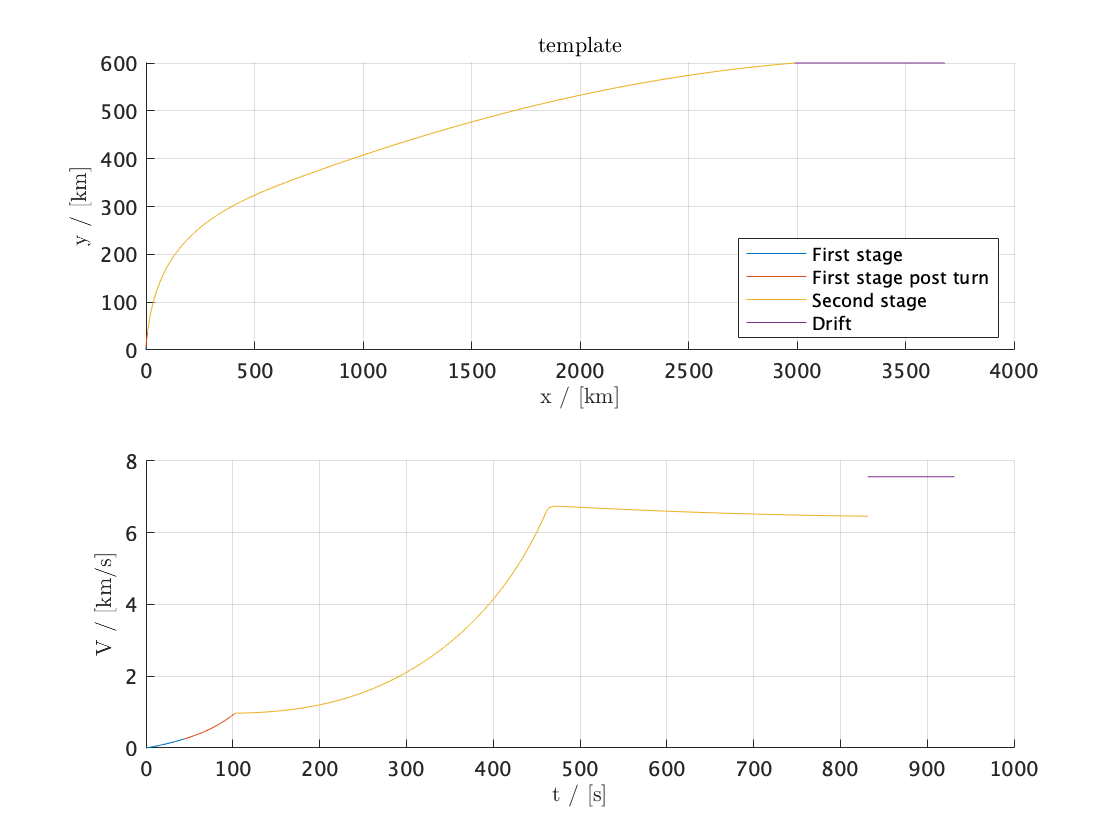

drift_duration = 100; % Seconds to plot the second stage in the right orbit.
plot_name = "template";

simulate_two_stage_rocket(stage_1, stage_2, burn_rates, fuel_left_in_first_stage, ...
        programmed_turn_height, programmed_turn_angle, ...
        target_altitude, ...
        drift_duration, plot_name)